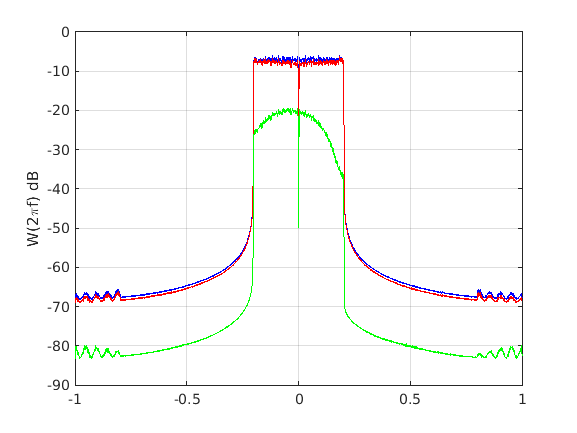

% это собственный LMS (нужен)
clear all
close all
% 80 'x'=x, 'y'=d, 200 'x'=x, 'y'=y
% load('gsm_4c_in');
% load('gsm_4c_out');
load('linear_lte_2c_data0_in');
load('linear_lte_2c_data0_out');
% load('linear_lte_2c_data1_in');
% load('linear_lte_2c_data1_out');
% load('lte_2c_data0_in');
% load('lte_2c_data0_out');
% load('lte_2c_data1_in');
% load('lte_2c_data1_out');
% load('lte_4c_data0_in');
% load('lte_4c_data0_out');
% load('lte_10c_data0_in');
% load('lte_10c_data0_out');
in = x.';
out = y.';
e = out - in;
e_new =  zeros(1, length(x));
X = 10*log10(pwelch(in, 2048));
X1(1:length(X)/2) = X(length(X)/2+1:end);
X1(length(X)/2+1:length(X)) = X(1:length(X)/2);
Y = 10*log10(pwelch(out, 2048));
Y1(1:length(Y)/2) = Y(length(Y)/2+1:end);
Y1(length(Y)/2+1:length(Y)) = Y(1:length(Y)/2);
E = 10*log10(pwelch(out-in, 2048));
E1(1:length(E)/2) = E(length(E)/2+1:end);
E1(length(E)/2+1:length(E)) = E(1:length(E)/2);
plot(linspace(-1, 1, length(X1)), X1,'b');
hold on
plot(linspace(-1, 1, length(Y1)), Y1,'r');
hold on
plot(linspace(-1, 1, length(E1)), E1,'g');
ylabel('W(2\pif) dB')
grid on
p1 = 1;
for K = 4:2:8
    p2 = 1;
    in1 = zeros(length(x) + K, 1);
    in1(1+K/2:length(x)+K/2, 1) = in;
    for mu = 0.12:0.01:0.19
        st = 2; % степень полинома
        weights = zeros(st*(K+1), 1);
        for nn = 1:20
            m = 1;
            for n = K/2+1:length(in)+K/2
                t = 1;
                for k = K/2:-1:-K/2
                    U(t:t+st-1) = [in1(n+k) in1(n+k)*abs(in1(n+k))];
                    t = t + st;
                end
                signal_out(m) = weights.' * U.';
                err(m) = out(m) - signal_out(m) ;
                weights = weights + mu*err(m)*U';
                m=m+1;
            end
        end
        e_mod =  out - signal_out.';
        E_mod = 10*log10(pwelch(e_mod, 2048)); % ошибка ошибки
        hold on
        E_mod1(1:length(E_mod)/2) = E_mod(length(E_mod)/2+1:end);
        E_mod1(length(E_mod)/2+1:length(E_mod)) = E_mod(1:length(E_mod)/2);
        NMSE(p1, p2) = 10*log10((e_mod'*e_mod)/(in'*in));
        p2 = p2 + 1;
    end
    p1 = p1 + 1;
end

figure
[XX,YY] = meshgrid(4:2:8,0.18:0.01:0.22);
contourf(XX, YY, NMSE.', [-28.64 -28.634 -27:0.5:-25 -20:1:-1 0]);
grid on
xlabel('K');
ylabel('\mu');